clear all
x = linspace(25,85,7);
f =[20 35 50 49 25 15 6]';
xbar = (x*f)/200;
var = ((x'-xbar).^2)'*f/200;


%%
%simulación de un número n de datos de la tabla
n=10000; %En la tabla son 20 pero aca lo cambiamos a 1000
n1=floor(0.1*n); %floor para que quede un número entero
n2=floor(0.175*n);
n3=floor(0.25*n);
n4=floor(0.245*n);
n5=floor(0.125*n);
n6=floor(0.075*n);
n7=floor(0.03*n);

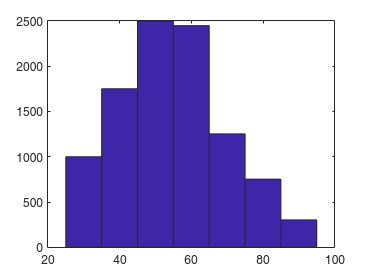

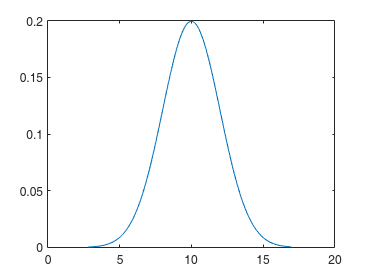


%%
%simular números aleatorios uniformes en el intervalo [a,b] es
%a+(b-a)*rand(n,1)
d1=25+10*rand(n1,1);
d2=35+10*rand(n2,1);
d3=45+10*rand(n3,1);
d4=55+10*rand(n4,1);
d5=65+10*rand(n5,1);
d6=75+10*rand(n6,1);
d7=85+10*rand(n7,1);
ds=[d1
    d2
    d3
    d4
    d5
    d6
    d7]; %datos simulados

media=mean(ds);
mediana=median(ds);
p30=prctile(ds,30);
p25=prctile(ds,25);
p75=prctile(ds,75);
hist(ds,7)

n = 100, K = 15;

n = 100


%Simulacion de datos multivariantes con las mismas propiedades
X1 = [randn(n,1), wblrnd(1,2,n,1), exprnd(2,n,1), randn(n,1)];
table1 = tabulate(X1(:,1))

table1 =    -3.1058    1.0000    1.0000
   -2.2665    1.0000    1.0000
   -1.8739    1.0000    1.0000
   -1.7594    1.0000    1.0000
   -1.6998    1.0000    1.0000
   -1.6919    1.0000    1.0000
   -1.5859    1.0000    1.0000
   -1.4852    1.0000    1.0000
   -1.3848    1.0000    1.0000
   -1.1750    1.0000    1.0000


table2 = tabulate(X1(:,2))

table2 =     0.0668    1.0000    1.0000
    0.1686    1.0000    1.0000
    0.2176    1.0000    1.0000
    0.2284    1.0000    1.0000
    0.2645    1.0000    1.0000
    0.2685    1.0000    1.0000
    0.2708    1.0000    1.0000
    0.2752    1.0000    1.0000
    0.2906    1.0000    1.0000
    0.2989    1.0000    1.0000


table3 = tabulate(X1(:,3))

table3 =     0.0064    1.0000    1.0000
    0.0186    1.0000    1.0000
    0.0250    1.0000    1.0000
    0.0295    1.0000    1.0000
    0.0518    1.0000    1.0000
    0.0650    1.0000    1.0000
    0.0843    1.0000    1.0000
    0.0845    1.0000    1.0000
    0.0974    1.0000    1.0000
    0.1556    1.0000    1.0000


table4 = tabulate(X1(:,4))

table4 =    -2.6681    1.0000    1.0000
   -1.9492    1.0000    1.0000
   -1.5982    1.0000    1.0000
   -1.5468    1.0000    1.0000
   -1.5184    1.0000    1.0000
   -1.5168    1.0000    1.0000
   -1.3980    1.0000    1.0000
   -1.3797    1.0000    1.0000
   -1.3496    1.0000    1.0000
   -1.3034    1.0000    1.0000



table = [cumsum(table1(:,3)) cumsum(table2(:,3)) cumsum(table3(:,3)) cumsum(table4(:,3))]

table =      1     1     1     1
     2     2     2     2
     3     3     3     3
     4     4     4     4
     5     5     5     5
     6     6     6     6
     7     7     7     7
     8     8     8     8
     9     9     9     9
    10    10    10    10



N = 100

N = 100


a = zeros(N,4);
for i=1:N
num = rand(1);

vars = [find(table(:,1)>num*100,1,"first")
    find(table(:,2)>num*100,1,"first")
    find(table(:,3)>num*100,1,"first")
    find(table(:,4)>num*100,1,"first")];

a1 = [table1(vars(1)-1), table1(vars(1))];
a2 = [table2(vars(2)-1), table2(vars(2))];
a3 = [table3(vars(3)-1), table3(vars(3))];
a4 = [table4(vars(4)-1), table4(vars(4))];

a(i,:) = [unifrnd(a1(1), a1(2))
    unifrnd(a2(1), a2(2))
    unifrnd(a3(1), a3(2))
    unifrnd(a4(1), a4(2))]';
end

a(:,:)

ans =    -0.2092    0.7383    0.8874   -0.3446
   -1.6243    0.2696    0.0706   -1.4311
   -0.0844    0.8282    1.0138   -0.1495
    1.9215    1.8321    6.2960    1.5573
   -0.5988    0.5619    0.5367   -0.6071
    0.0368    0.9611    1.2976   -0.0051
   -0.6208    0.5596    0.5124   -0.6354
   -1.6402    0.2706    0.0745   -1.4593
   -0.6095    0.5623    0.5333   -0.6073
   -0.1955    0.7538    0.8920   -0.3426


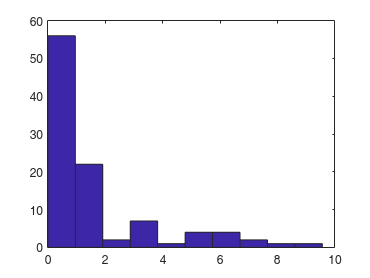

clf
hist(a(:,3))

mean(a)

ans =    -0.1408    0.8553    1.6838   -0.1830


std(a)

ans =     1.0487    0.5020    2.0779    0.9779


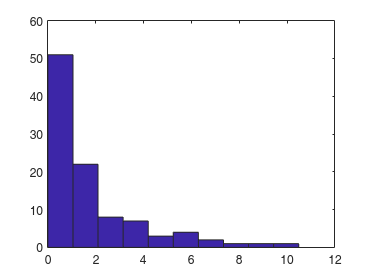


hist(X1(:,3))

mean(X1)

ans =    -0.0339    0.9092    1.8283   -0.0622


std(X1)

ans =     0.9964    0.4949    2.0448    0.9300
